# Laplace transforms with MATLAB and the symbolic toolbox

This note focuses on Laplace transforms and inverse Laplace.  These are somewhat tedious on pen and paper so MATLAB is useful to check your working or understanding and indeed, to do the computations in the first place. Laplace is a core tool in elementary feedback and behaviour analysis and thus understanding how to use MATLAB to support this is an enormous time saver. 

Some of the laplace tools use symbolic variables so the first thing to do is to create suitable symbolic variables. These variables facilitate algebra and thus are different from typical variables which contain numbers.

You must have the symbolic toolbox installed for this file to work.

Later files on closed-loop analysis and behaviours focus more on the use of ***tf.m*** which is part of the control toolbox and these do not use symbolic toolbox.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Creating symbolic variables

- Find Laplace transforms from a time domain signal 

- Inverse Laplace transforms

- Using subs.m to turn symbolic expressions into numbers 

- Final values from transforms

- Compare solutions from ilaplace.m and dsolve.m

## 1. Creating symbolic variables

Use "whos" to interrogate the different variable types created in the code snippet below. 

clear 
x = 3.1

x = 3.1000

y = [2 4]

y =      2     4


syms t s 
whos

  Name      Size            Bytes  Class     Attributes

  s         1x1                 8  sym                 
  t         1x1                 8  sym                 
  x         1x1                 8  double              
  y         1x2                16  double              



A "double" is a variable that contains numerical data whereas "sym" has no number attached and can be used for algebra, for example try these snippets.

xy = x*y

xy =     6.2000   12.4000


ts = t*s

$$ts = s\,t$$

xt = x*t

$$xt = \frac{31\,t}{10}$$

#### NOTE: The Laplace tools to be used next require  symbolic variables; to avoid confusion it is better to USE t for time and s for Laplace; but this is NOT NECESSARY! 

## 2. Find Laplace transforms from a time domain signal 

We will be familiar with the definition of Laplace given as:


$$X\left(s\right)=L\left\lbrack x\left(t\right)\right\rbrack =\int_0^{\infty } x\left(t\right)e^{-\textrm{st}} \textrm{dt}\;$$


The function ***laplace.m*** will do this integral for a sensible range of typical engineeering signals as illustrated in the code snippets below. 

- First define x(t) using a symbolic variable 't'

- Then use laplace.m

Try changing the values in the lines below to create your own examples. For clarity here, lower case is used for time domain and upper case for Laplace.

disp('BELOW is SECTION 2')

BELOW is SECTION 2



syms t

x=exp(-0.2*t)

$$x = {\mathrm{e}}^{-\frac{t}{5}}$$

X=laplace(x)

$$X = \frac{1}{s+\frac{1}{5}}$$


y=sin(4*t)

$$y = \sin\left(4\,t\right)$$

Y=laplace(y)

$$Y = \frac{4}{s^{2}+16}$$


z = exp(-5*t)*cos(0.2*t)

$$z = \cos\left(\frac{t}{5}\right)\,{\mathrm{e}}^{-5\,t}$$

Z=laplace(z)

$$Z = \frac{s+5}{{\left(s+5\right)}^{2}+\frac{1}{25}}$$


f=t*exp(-4*t)+3

$$f = t\,{\mathrm{e}}^{-4\,t}+3$$

F=laplace(f)

$$F = \frac{1}{{\left(s+4\right)}^{2}}+\frac{3}{s}$$

## 3. Inverse Laplace transforms

By hand one would typically do inverse Laplace using a table of transforms and manipulating the  transform into the forms in the table; this is somewhat laborious.

The file ***ilaplace.m*** will do this for you but with a warning. MATLAB will often not simplify somethings that you would like too and may express things in fractions rather than decimals and so forth. Lets try to do inverse Laplace transforms of examples from the previous section.

disp('BELOW is SECTION 3')

BELOW is SECTION 3



% If the transform is provided
xt = ilaplace(X)

$$xt = {\mathrm{e}}^{-\frac{t}{5}}$$

yt = ilaplace(Y)

$$yt = \sin\left(4\,t\right)$$

zt = ilaplace(Z)

$$zt = \cos\left(\frac{t}{5}\right)\,{\mathrm{e}}^{-5\,t}$$

ft = ilaplace(F)

$$ft = t\,{\mathrm{e}}^{-4\,t}+3$$

Or define the Laplace directly.

syms s
x1 = ilaplace(-0.3/(s+0.25))

$$x1 = -\frac{3\,{\mathrm{e}}^{-\frac{t}{4}}}{10}$$

x2 = ilaplace(15/(s*(s+5)))

$$x2 = 3-3\,{\mathrm{e}}^{-5\,t}$$

x3 = ilaplace(9/(4*s^3+8*s^2))

$$x3 = \frac{9\,t}{8}+\frac{9\,{\mathrm{e}}^{-2\,t}}{16}-\frac{9}{16}$$

x4 = ilaplace(9*(s+2)/(4*s^3+8*s^2+4*s))

$$x4 = \frac{9}{2}-\frac{9\,t\,{\mathrm{e}}^{-t}}{4}-\frac{9\,{\mathrm{e}}^{-t}}{2}$$

#### Warning: ilaplace.m will take whatever symbolic variable is in your function and assume this represents 's'. For example, see the examples below: 

disp('Examples G, H and K below')

Examples G, H and K below


syms w k s
G=(w+3)/(w^2+2*w+6)

$$G = \frac{w+3}{w^{2}+2\,w+6}$$

gt = ilaplace(G)

$$gt = {\mathrm{e}}^{-t}\,\left(\cos\left(\sqrt{5}\,t\right)+\frac{2\,\sqrt{5}\,\sin\left(\sqrt{5}\,t\right)}{5}\right)$$


H=9*(k+2)/(4*k^3+8*k^2+4*k)

$$H = \frac{9\,k+18}{4\,k^{3}+8\,k^{2}+4\,k}$$

ht = ilaplace(H)

$$ht = \frac{9}{2}-\frac{9\,t\,{\mathrm{e}}^{-t}}{4}-\frac{9\,{\mathrm{e}}^{-t}}{2}$$


K=0.4/((2*s^2+8*s+3)*(s+0.8))

$$K = \frac{2}{5\,\left(s+\frac{4}{5}\right)\,\left(2\,s^{2}+8\,s+3\right)}$$

kt=ilaplace(K)

$$kt = \frac{10\,{\mathrm{e}}^{-2\,t}\,\left(\cosh\left(\frac{\sqrt{2}\,\sqrt{5}\,t}{2}\right)+\frac{6\,\sqrt{2}\,\sqrt{5}\,\sinh\left(\frac{\sqrt{2}\,\sqrt{5}\,t}{2}\right)}{25}\right)}{53}-\frac{10\,{\mathrm{e}}^{-\frac{4\,t}{5}}}{53}$$

## 4. Using subs.m to turn symbolic expressions into numbers 

Once you have performed an inverse Laplace, you may want to determine the value of the time domain signal at different times to create a plot. Symbolic expressions can be evaluated using the file subs.m which is short for substitute, that is, substitute in this value for 't' and tell me the value.

Look at this simple example

disp('BELOW is SECTION 4')

BELOW is SECTION 4


disp(' ');

syms t
f = t^2.

$$f = t^{2}$$

t_values=[0,1,2,3,4,5]   %% numerical values to be given to 't'

t_values =      0     1     2     3     4     5


ft = subs(f,t_values)

$$ft = \left(\begin{array}{cccccc} 0 & 1 & 4 & 9 & 16 & 25 \end{array}\right)$$

In general, once we have done the inverse Laplace and determined the time domain signal, we will want to plot this over a given time domain (see the plotting file for more guidance), so the following code gives a simple illustration. Note how ***subs*** may not express the answer in decimal but rather as exact expressions - use eval.m to find the underlying number as a decimal.

syms w
t_values = linspace(0,4,50)    %% times we want the plot for

t_values =          0    0.0816    0.1633    0.2449    0.3265    0.4082    0.4898    0.5714    0.6531    0.7347    0.8163    0.8980    0.9796    1.0612    1.1429    1.2245    1.3061    1.3878    1.4694    1.5510    1.6327    1.7143    1.7959    1.8776    1.9592    2.0408    2.1224    2.2041    2.2857    2.3673    2.4490    2.5306    2.6122    2.6939    2.7755    2.8571    2.9388    3.0204    3.1020    3.1837    3.2653    3.3469    3.4286    3.5102    3.5918    3.6735    3.7551    3.8367    3.9184    4.0000


G=(w+3)/(w^2+2*w+6)

$$G = \frac{w+3}{w^{2}+2\,w+6}$$

gt = ilaplace(G)

$$gt = {\mathrm{e}}^{-t}\,\left(\cos\left(\sqrt{5}\,t\right)+\frac{2\,\sqrt{5}\,\sin\left(\sqrt{5}\,t\right)}{5}\right)$$

g_values = subs(gt,t_values)

g_numbers =eval(g_values)

g_numbers =     1.0000    1.0559    1.0646    1.0328    0.9679    0.8771    0.7678    0.6467    0.5201    0.3934    0.2713    0.1577    0.0553   -0.0336   -0.1079   -0.1671   -0.2112   -0.2409   -0.2572   -0.2617   -0.2558   -0.2414   -0.2204   -0.1943   -0.1651   -0.1342   -0.1030   -0.0727   -0.0444   -0.0186    0.0039    0.0229    0.0382    0.0498    0.0578    0.0625    0.0642    0.0633    0.0601    0.0553    0.0491    0.0421    0.0345    0.0269    0.0194    0.0123    0.0058    0.0001   -0.0047   -0.0087


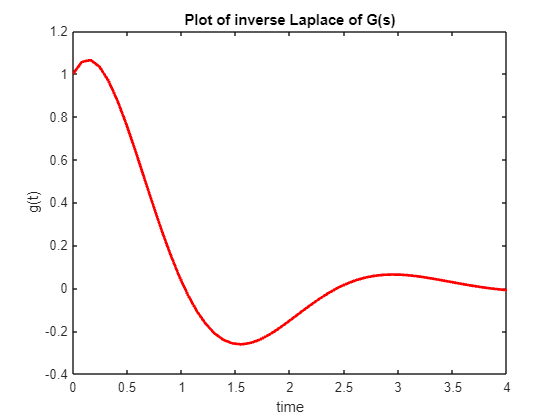

figure
plot(t_values,g_numbers,'r','linewidth',2)
xlabel('time')
ylabel('g(t)')
title('Plot of inverse Laplace of G(s)')

## 5. Final values from transforms

The FVT theorem is simplest. To check with MATLAB, you can find the final value by letting time go to infinity and doing a plot.

disp('BELOW is SECTION 5')

BELOW is SECTION 5


syms s
X1 = -0.3/(s+0.25)

$$X1 = -\frac{3}{10\,\left(s+\frac{1}{4}\right)}$$

x1 = ilaplace(X1)

$$x1 = -\frac{3\,{\mathrm{e}}^{-\frac{t}{4}}}{10}$$

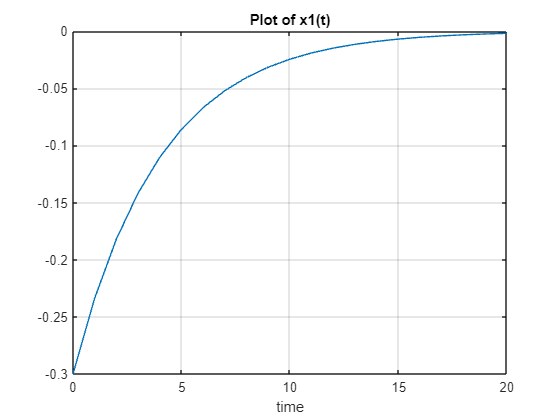

tt = 0:1:20; plot(tt,subs(x1,tt)); 
title('Plot of x1(t)'); 
xlabel('time')
grid

Alternatively, set s=0 using subs and do the FVT directly

x1_ss = subs(s*X1,0)

$$x1\_ss = 0$$


X2 = 3/(s*(s+4))

$$X2 = \frac{3}{s\,\left(s+4\right)}$$

x2 = ilaplace(X2)

$$x2 = \frac{3}{4}-\frac{3\,{\mathrm{e}}^{-4\,t}}{4}$$

x2_ss = subs(s*X2,0)

$$x2\_ss = \frac{3}{4}$$

## 6. Compare solutions from ilaplace.m and dsolve.m

You can use Laplace or other mathematics (e.g. ***dsolve.m***) to solve ODEs. The code below illustrates that both methods give the same solution.

%% define some signals
disp('BELOW is SECTION 6')

Below is section 6


syms x(t)
Dx=diff(x); D2x = diff(Dx);
x=dsolve(2*D2x+8*Dx+6*x==0.4*exp(-4*t),x(0)==0, Dx(0)==0)

$$x = \frac{{\mathrm{e}}^{-4\,t}\,\left({\mathrm{e}}^{3\,t}-3\,{\mathrm{e}}^{t}+2\right)}{30}$$

X = 0.4/((s+4)*(2*s^2+8*s+6));
xt = ilaplace(X)

$$xt = \frac{{\mathrm{e}}^{-t}}{30}-\frac{{\mathrm{e}}^{-3\,t}}{10}+\frac{{\mathrm{e}}^{-4\,t}}{15}$$


%% define some signals
syms y(t) t s
Dy=diff(y); D2y = diff(Dy);
y = dsolve(40*D2y+160*Dy+120*y==60,y(0)==0, Dy(0)==0)

$$y = \frac{{\mathrm{e}}^{-3\,t}}{4}-\frac{3\,{\mathrm{e}}^{-t}}{4}+\frac{1}{2}$$

Y = 60/(s*(40*s^2+160*s+120));
yt = ilaplace(Y)

$$yt = \frac{{\mathrm{e}}^{-3\,t}}{4}-\frac{3\,{\mathrm{e}}^{-t}}{4}+\frac{1}{2}$$


%% 
x0=-1;
X=(0.2/s +x0)/(2+0.4*s)

$$X = \frac{\frac{1}{5\,s}-1}{\frac{2\,s}{5}+2}$$

xt = ilaplace(X)

$$xt = \frac{1}{10}-\frac{13\,{\mathrm{e}}^{-5\,t}}{5}$$


%%
w0=0; wd0=0;
W = (3/s +s*w0+wd0)/(s^2+2*s+4)

$$W = \frac{3}{s\,\left(s^{2}+2\,s+4\right)}$$

wt = ilaplace(W)

$$wt = \frac{3}{4}-\frac{3\,{\mathrm{e}}^{-t}\,\left(\cos\left(\sqrt{3}\,t\right)+\frac{\sqrt{3}\,\sin\left(\sqrt{3}\,t\right)}{3}\right)}{4}$$